# **Exámen Final de Prácticas Recuperación 2016-2017**

#### **Problema 1**

Junto al problema se nos muestra una escala musical con la frecuencia correspondiente a cada nota

1.- Crear un vector de frecuencias que se llame "escala" que contenga las frecuencias de la escala musical de menor a mayor

2.- Generar un audio en el que se escuchen todas las notas de la escala musical desde la más grave a la más aguda. La duración de cada nota será de 1 segundo y se trabajará con una frecuencia de muestreo de 44100Hz. Guarda el sonido en audio en formato wav con el nombre "escala.wav"

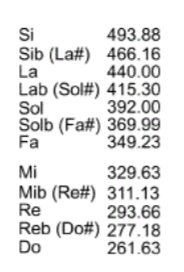

Para poder realizar un vector es bastante simple

Escala = [261.3 277.18 293.66 311.13 329.63 349.23 369.99 392 415.30 440 466.16 493.88];

Nos indican que la duración de cada uno debe de ser de 1 segundo

Duracion = 1;
Fs = 44100;

Obtenemos el periodo a partir de hacer la inversa de la frecuencia de muestreo

Ts = 1/Fs;

Creamos el vector de tiempos hasta 1 segundo

t = 0:Ts:Duracion-Ts;

Inicializamos la variable de salida

Y = 0;

A continuación el bucle con el cual calcularemos el valor del tono

for i = 1:length(Escala)

La ecuación que utilizaremos para la creación del tono

    Tono = cos(2*pi*Escala(i)*t);
    Y = [Y Tono];
end

Guardamos el audio como un .wav

audiowrite('Escala.wav', Y, Fs);

A continuación se nos pode obtener la Fs del audio nessum.wav

Para cargar un audio utilizaremos audioread

[x, fs] = audioread('nessum.wav');

Podemos observar que es mono porque solo tiene una columna

A continuación transponemos y pasamos a vector horizontal

x = x(:,1);

#### Problema 2. Vibrato

[Y] = vibrato(escala, fs, alpha, fm);

#### Problema 2 Glissandro

[Y] = glissandro(fs, nota1, nota2, TAU, duracion_nota);

#### Problema 3 Chorus

[Y] = chorus(x, g, fs, RET);

#### Problema 2. Vibrato y Glissandro

**Vibrato**

Vibrato, es un término musical que describe la variación periódica de frecuencia de un sonido. Se trata de un efecto musical que se utiliza para añadir expresión a la música vocal e instrumental.

La expresión general de un tono puro con el efecto vibrato es:

Dónde alfa es la profundidad de modulación (1 de máximo y 0 no existe modulación)

fm es la frecuencia de vibración

Programa una función que reproduzca el efecto vibrato para todas las notas de la escala musical del apartado 1 tomando para la duración de cada nota un valor de 1s. Guarda la función con el nombre vibrato.m. Aplícala utilizando α=0,005 y fm=5. Guarda el archivo de audio generado con el nombre vibr.wav. 

function [Y] = vibrato(escala, fs, alpha, fm)

El enunciado nos indica que la duración de cada nota será de 1 segundo

Duracion = 1;

El número de muestras que hay en una nota

N = Duracion*fs;

Creamos el vector de tiempo

t = [0:N-1]/fs;

Inicializamos la variable de salida

Y = 0;

Generamos la variable Variación, recordemos que tenemos un 5% de variación, alpha  = 0.005

Variacion = alpha*cos(2*pi*fm.*t);

Creamos el bucle para el calculo de fn

for i=1:length(escala)
    fn = escala(i)*Variacion;

Una vez tenemos fn podemos calcular la salida Y

    Y = [Y sin(2*pi*(escala(i)+fn).*t)];
end

Almacenamos el audio

audiowrire('vibr.wav', Y, fs);
end

**Glissandro**

Por otro lado, glissandro un efecto sonoro consistente en pasar rápidamente de un sonido hasta otro más agudo o más grave haciendo que se escuchen todos los sonidos intermedios posibles dependiendo de las características del instrumento. Para ello, al pasar de una nota a otra, habrá un período de transición τ, en el que la frecuencia del tono variará de forma lineal, desde la frecuencia inicial hasta la frecuencia final 

Se pide desarrollar un script o función que realice el efecto glissandro entre dos notas de la escala definida en el apartado 1. Guarda la función con el nombre glissandro.m. Aplícala para hacer la transición entre la primera y cuarta nota de la escala, utilizando tau=0,5 y duracion_notas=2. Guarda el archivo de audio generado con el nombre gliss.wav 

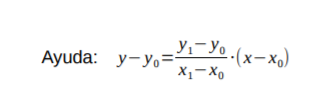

function [Y] = glissandro(fs, nota1, nota2, TAU, Duracion)

Empezamos calculando el número de muestras que hay en una nota

N = Duracion*fs;

Creamos el vector de tiempos

t = [0:N-1]/fs;

Inicializamos el vector de salida

Y = 0;

Ahora crearemos el vector de tiempo del efecto glissandro

t2 = [0:(TAU*fs)-1]/fs;

La frecuencia variará linealmente entre la nota1 y la nota2, durante un periodo de valor TAU. Utilizaremos la ecuación de la recta dónde la ordenada es la frecuencia y la abscisa es el tiempo

F_Gliss = nota1+((nota2-nota1)/TAU)*t2;

El efecto glissandro

Gliss = cos(2*pi*F_Gliss.*t2);

Concatenamos con los tonos de las notas 1 y 2

Y = [cos(2*pi*nota1*t), Gliss, cos(2*pi*nota2*t)];

Almacenamos el audio

audiowrite('gliss.wav', Y, fs);
end

#### Problema 3

Realizar una función de matlab que a partir de una señal de entrada presente una salida una versión con el efecto chorus

Dónde:

- x es la señal de entrada

- g es el vector de ganancias de la señal original y los distintos ecos

- fs es la frecuencia de muestreo de la señal original

- RET es el retardo máximo permitido para las distintas voces

Procedimiento: 

- El vector g nos indicará el número total de voces del coro, incluyendo la voz original.

- El retardo de cada voz es aleatorio, pero con variaciones lentas . El retardo máximo vendrá dado por RET. (Recomendación: utilizar la función lowFreqNoise(n) que genera una señal aleatoria de baja frecuencia)

- Para dar la sensación de voces distintas modificaremos la frecuencia de cada voz del coro de forma aleatoria pero no podrán superarse los márgenes del ±10% de la frecuencia original. (Recomendación: utilizar interpolación y diezmado)

Parámetros de entrada:

g = [1 0.8 0.9 1 .0.7 1]

RET = 25ms

Señal de audio nessum.wav

function [Y] = chorus(x, g, fs, RET)

Obtenemos la longitud del vector x

Long_Audio = length(x);

Ruido Rojo

LowFreqNoise genera una señal aleatoria entre 0 y 1, igual que rand pero introduce variaciaciones lentas

Aleatorio = lowFreqNoise(Long_Audio);

Con disp mostramos el vector X sin necesidad de darle un nombre o más información

disp('Ruido Generado');

La función ceil redondea hacia arriba

Número total de muestras del retardo

N = ceil(RET*fs);

Creamos una reserva de memoria para el retardo

Retardo = zeros(N,1);

Inicializamos el vector de salida con la señal original sin retardar multiplicada por su ganancia

Y = x*g(1);

Creamos un bucle para el calculo de la señal.

g(1) es el original por lo que los ecos empeizan a partir del segundo elemento

for i=2:length(g)

Longitud del retardo

La función floor reodndea hacia abajo

    Long_Retardo = floor((RET+RET*Aleatorio(i))*fs); 

Introducimos el retardo antes de la señal orginal con lo que obtendremos una señal retardada

    Y1 = [Long_Retardo(:)' x(:)'];

Interpolaremos aleatoriamente entre 25 y 30 muestras para modificar la frecuencia.

En el caso más extremo:

Por abajo df = (25/30)*100 = 83.33% Disminución de la frecuencia en un 20% aprox

Por encima df = (30/25)*100 = 120% Incremento de la frecuencia en un 20% aprox

    disp('interpolaciones');

Generamos de forma aleatoria el número de muestras a interpolar y diezmar

    inter = 35+round(4*(rand(1,1)));
    diezmado = 35+round(4*(rand(1,1)));
    X1 = interp(Y1, inter);

Tras la interpolación y antes del diezmado, filtramos para evitar problemas de solapamiento

    [b, a] = butter(4, 0.75);
    X1 = filter(b, a, X1);
    X2 = decimate(X1, diezmado);

Nos aseguraremos que no habrá error al modificar el número de muestras

    aux = [length(Y), length(X2)];
    Long_Aux = max(aux);

Para poder sumar señales debemos de garantizar que tienen el mismo número de muestras

    Y = [Y(:)' zeros(1, Long_Aux-length(Y)+1)];
    X2 = [X2(:)' zeros(1, Long_Aux - length(x2)+1)];
    Y = Y + g(i) * X2;
end
end